# Correlation in Electricity Usage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

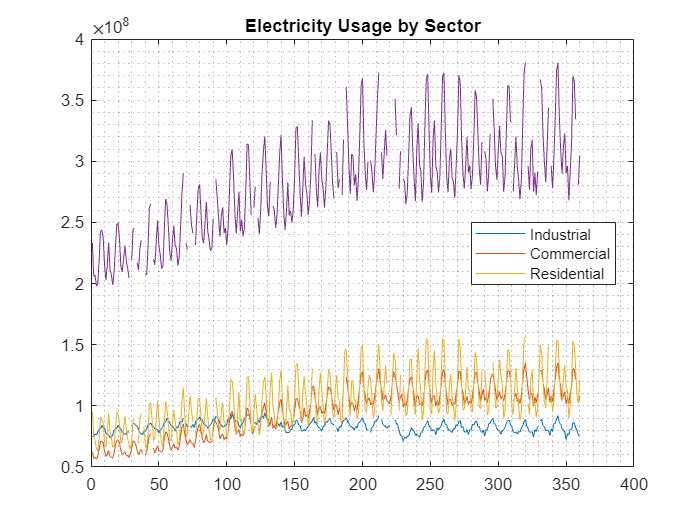

com = table2array(readtable("../data/electricity.xlsx", "Sheet", "com", "ReadVariableNames", false));
ind = table2array(readtable("../data/electricity.xlsx", "Sheet", "ind", "ReadVariableNames", false));
res = table2array(readtable("../data/electricity.xlsx", "Sheet", "res", "ReadVariableNames", false));
indV = ind(:);
comV = com(:);
resV = res(:);
usage = indV + comV + resV;
allSectors = [indV comV resV usage];
plot(allSectors)
grid minor
title("Electricity Usage by Sector")
legend("Industrial", "Commercial", "Residential",...
    "Location", "Best")

## Task 1

comResCorr = corrcoef(com, res, "Rows", "complete")

comResCorr =     1.0000    0.8288
    0.8288    1.0000


## Task 2

allCorr = corrcoef(allSectors, "Rows", "complete")

allCorr =     1.0000    0.2035    0.2065    0.3139
    0.2035    1.0000    0.8286    0.9473
    0.2065    0.8286    1.0000    0.9548
    0.3139    0.9473    0.9548    1.0000
